% Initialize symbols 
syms M m1 m2 l1 l2 g F t1 t2 x x_ t1_ t2_;

% Setup the functions after small angle approximation 
X_dotdot =(F - m1*g*t1 - m2*g*t2)/M;
t1_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t1)/(M*l1);
t2_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t2)/(M*l2);

% Setup state and input vectors
X_states = [x x_ t1 t1_ t2 t2_];
X_eq = [x_ X_dotdot t1_ t1_dotdot t2_ t2_dotdot];
U_input = F;

% Programmatically attain A matrix through Jacobian linearization
A_ = zeros(length(X_eq), length(X_states)) + x;
for i = 1:length(X_eq)
    for j = 1:length(X_states)
        A_(i, j) = diff(X_eq(i), X_states(j));
    end
end
disp(A_)

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{M\,g+g\,m_{1}}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{M\,g+g\,m_{2}}{M\,l_{2}} & 0 \end{array}\right)$$


% Programmatically attain B matrix through Jacobian linearization
B_ = zeros(length(X_states), length(U_input)) + x;
for i = 1:length(U_input)
    for j = 1:length(X_eq)
        B_(j, i) = diff(X_eq(j), U_input(i));
    end
end
disp(B_)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$


% Test to check for Controllability of Symbolic Matrices
n = size(A_, 1); 
ControllabilityMatrix = zeros(n) + x;
ControllabilityMatrix(:,1) = B_;

for i = 1:(n - 1)
    ControllabilityMatrix(:,i+1) = A_^i * B_;
end
disp(ControllabilityMatrix)

$$\begin{array}{l} \left(\begin{array}{cccccc} 0 & \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4}\\ \frac{1}{M} & 0 & \sigma_{1} & 0 & \sigma_{4} & 0\\ 0 & \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{3}\\ \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{3} & 0\\ 0 & \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2}\\ \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{g\,m_{1}}{M^{2}\,l_{1}}-\frac{g\,m_{2}}{M^{2}\,l_{2}}\\ \sigma_{2}=\frac{\frac{{\sigma_{7}}^{2}}{M^{2}\,{l_{2}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{8}}}{M\,l_{2}}+\frac{\frac{g\,m_{1}\,\sigma_{7}}{M^{2}\,{l_{2}}^{2}}+\frac{g\,m_{1}\,\sigma_{9}}{\sigma_{8}}}{M\,l_{1}}\\ \sigma_{3}=\frac{\frac{{\sigma_{9}}^{2}}{M^{2}\,{l_{1}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{8}}}{M\,l_{1}}+\frac{\frac{g\,m_{2}\,\sigma_{9}}{M^{2}\,{l_{1}}^{2}}+\frac{g\,m_{2}\,\sigma_{7}}{\sigma_{8}}}{M\,l_{2}}\\ \sigma_{4}=\frac{\frac{g\,m_{1}\,\sigma_{9}}{M^{2}\,l_{1}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{2}}}{M\,l_{1}}+\frac{\frac{g\,m_{2}\,\sigma_{7}}{M^{2}\,l_{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{1}}}{M\,l_{2}}\\ \sigma_{5}=-\frac{\sigma_{7}}{M^{2}\,{l_{2}}^{2}}-\frac{g\,m_{1}}{\sigma_{8}}\\ \sigma_{6}=-\frac{\sigma_{9}}{M^{2}\,{l_{1}}^{2}}-\frac{g\,m_{2}}{\sigma_{8}}\\ \sigma_{7}=M\,g+g\,m_{2}\\ \sigma_{8}=M^{2}\,l_{1}\,l_{2}\\ \sigma_{9}=M\,g+g\,m_{1} \end{array}$$


% Condition of System Parameters for Controllability 
det_ControllabilityMatrix = det(ControllabilityMatrix);
disp('Determinant of the controllability matrix is');

Determinant of the controllability matrix is


disp(det_ControllabilityMatrix)

$$-\frac{g^{6}\,{l_{1}}^{2}-2\,g^{6}\,l_{1}\,l_{2}+g^{6}\,{l_{2}}^{2}}{M^{6}\,{l_{1}}^{6}\,{l_{2}}^{6}}$$


disp('size of system is');

size of system is


disp(n)

     6




% Checking rank of Matrix
rank_ControllabilityMatrix = rank(ControllabilityMatrix);
disp('Rank of C is');

Rank of C is


disp(rank_ControllabilityMatrix)

     6




if rank_ControllabilityMatrix == n
    disp('Rank(C)=n, controllable');
else
    disp('Rank(C)<n, not controllable。');
end

Rank(C)=n, controllable



% Setup C and D Matrices
C = eye(6);

D = 0;

% Set Initial Condition
X0 = [0 ; 0.1 ; 10 ; 0.2 ; 5 ; 0.3];

% Set System Parameters
M_v = 1000;
m1_v = 100;
m2_v = 100;
l1_v = 20;
l2_v = 10;
g_v = 9.8;

% Substitute System Parameters into Symbolic Matrices
A = double(subs(A_, {M m1 m2 l1 l2 g}, {M_v m1_v m2_v l1_v l2_v g_v}))

A =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0


B = double(subs(B_, {M l1 l2}, {M_v l1_v l2_v}))

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



% Checking Controllability with System Parameters
val_ControllabilityMatrix = ctrb(A,B)

val_ControllabilityMatrix = 1.0e-03 *

         0    1.0000         0   -0.1470         0    0.1417
    1.0000         0   -0.1470         0    0.1417         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1127         0    0.1246
    0.1000         0   -0.1127         0    0.1246         0



if (rank(val_ControllabilityMatrix)==6)
    disp(['Having full rank (equal to ', num2str(rank(val_ControllabilityMatrix)), '), the pair A,B is not controllable'])
else
    disp(['Not having full rank (equal to ', num2str(rank(val_ControllabilityMatrix)), '), the pair A,B is not controllable'])
end

Having full rank (equal to 6), the pair A,B is not controllable


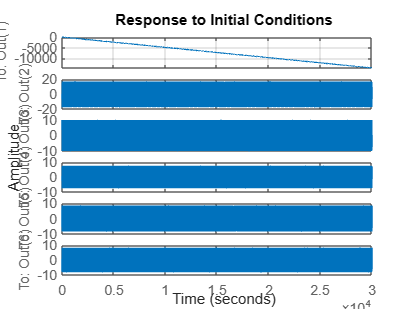



% Setup Gain Matrices
R = 0.0001;
Q1 = 1;
Q2 = 100;
Q3 = 1;
Q4 = 100;
Q5 = 10;
Q6 = 10;

Q = diag([Q1, Q2, Q3, Q4, Q5, Q6]);

% Setup Initial State Equation
system_behaviour = ss(A,B,C,D);

figure(1)
initial(system_behaviour,X0)
grid on


% Find LQR Gain Matrix
[K, P, poles] = lqr(A,B,Q,R)

K = 1.0e+03 *

    0.1000    1.1165    0.2276    0.0670    0.0956   -0.0390


P = 1.0e+03 *

    0.0112    0.0123    0.0007   -0.0246   -0.0004   -0.0110
    0.0123    0.1376    0.0321   -0.2738    0.0066   -0.1229
    0.0007    0.0321    2.7807   -0.0498   -0.0166   -0.0688
   -0.0246   -0.2738   -0.0498    5.6584    0.0685   -0.0243
   -0.0004    0.0066   -0.0166    0.0685    1.1743   -0.0049
   -0.0110   -0.1229   -0.0688   -0.0243   -0.0049    1.2026


poles =   -0.0200 + 0.7120i
  -0.0200 - 0.7120i
  -0.0320 + 1.0149i
  -0.0320 - 1.0149i
  -0.1007 + 0.0000i
  -0.9113 + 0.0000i


system_stable = 'true' ;

for i=1:6
    if(real(poles(i,1))>0)
        system_stable = 'false';
        break
    end
end

if (strcmp(system_stable,'true'))
    disp("Under the chosen and calculated parameters for the LQR controller, the system is stable using Lyapunov's Indirect Method")
else
    disp("Under the chosen and calculated parameters for the LQR controller, the system is not stable using Lyapunov's Indirect Method")
end

Under the chosen and calculated parameters for the LQR controller, the system is stable using Lyapunov's Indirect Method


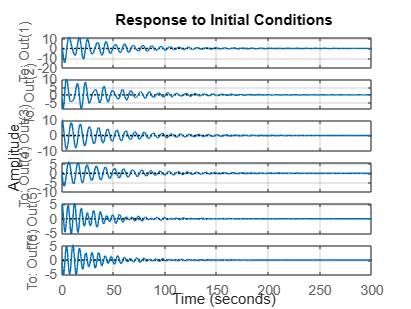


% Build New State Space Equation with LQR
new_B = [0 ; 0 ; 0 ; 0 ; 0 ; 0];
lqr_system_behavior = ss(A-(B*K),new_B,C,D);

% Simulate Linear System
figure(2)
initial(lqr_system_behavior,X0)
grid on

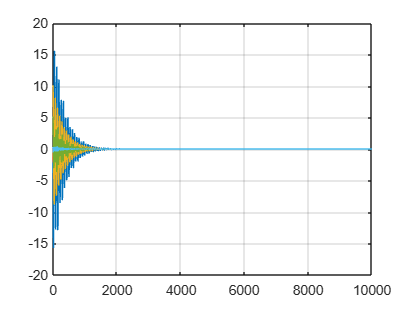


% Nonlinear System Simulation
time_period = 0:0.01:10000 ;
[t,X] = ode45(@(t,X) nonlinearfeedback(t, X, K, M_v, m1_v, m2_v, l1_v, l2_v, g_v),time_period,X0);
figure(3)
plot(t,X)
grid on

function y_dot = nonlinearfeedback(t, X, K, M, m1, m2, l1, l2, g)
F = -K*X ;
y_dot = zeros(6,1) ;
y_dot(1,1) = X(2) ;
y_dot(2,1) = (1/(M+m1+m2))*(F+(m1*l1*y_dot(4,1)*cosd(X(3)))+(m2*l2*y_dot(6,1)*cosd(X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))));
y_dot(3,1) = X(4) ;
y_dot(4,1) = (y_dot(2,1)*cosd(X(3))-g*(sind(X(3))))/l1 ;
y_dot(5,1) = X(6) ;
y_dot(6,1) = (y_dot(2,1)*cosd(X(5))-g*(sind(X(5))))/l2 ;
end


